%EMAG Lab 5 -- Waveguide Properties

%Part 2 -- Plotting E and S for TE10
clear all;

numberOfPoints = 10;
zMax = 100E-3;
numberOfCycles = 4;

operatingFrequency = 10E9;
a = 50E-3;
b = a/2;

m = 1;
n = 0;

x = linspace(0, a, numberOfPoints);
y = linspace(0, b, numberOfPoints);
z = linspace(0, zMax, numberOfPoints);

[x, y, z] = meshgrid(x, y, z);

t = linspace(0, 100E-12*numberOfCycles, numberOfPoints);

H0 = 5;

mu_0 = 4E-7*pi;
epsilon_0 = 8.85E-12;


kx = m*pi/a;
ky = n*pi/b;


h = kx^2+ky^2;
h = sqrt(h);

eta = sqrt(mu_0/epsilon_0);
waveZ = cutoffFrequency(m, n, a, b)/operatingFrequency;
waveZ = 1 - waveZ^2;
waveZ = eta/sqrt(waveZ);

omega = 2*pi*operatingFrequency;
beta = getBeta(operatingFrequency, cutoffFrequency(m, n, a, b));

%Electric Field Phasors
phasorEx = j*omega*mu_0*ky*H0/h^2;
phasorEx = phasorEx*cos(kx*x).*sin(ky*y).*exp(-j*beta*z);

phasorEy = -j*omega*mu_0*kx*H0/h^2;
phasorEy = phasorEy*sin(kx*x).*cos(ky*y).*exp(-j*beta*z);

phasorEz = zeros(numberOfPoints, numberOfPoints, numberOfPoints);


%Magnetic Field Phasors
phasorHx = -phasorEy/waveZ;
phasorHy = phasorEx/waveZ;
phasorHz = H0*cos(kx*x).*cos(ky*y).*exp(-j*beta*z);



%Time ave Poynting Vector
% S = conj(phasorH);
% S = cross(phasorE, S);
% S = 0.5*real(S);

%Electric Field Vector
%E = real(phasorE.*exp(j*omega*t));

%Magnetic Field Vector
%H = real(phasorH.*exp(j*omega*t));

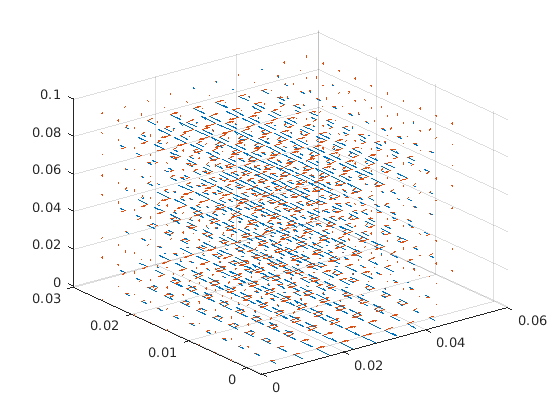

% Plot the Electric field with quiver3
set(gcf,'Visible','on')

figure(2)
%w = waitforbuttonpress

timeCount = 1E-12; %mod(k, numberOfPoints);
    
Ex = real(phasorEx.*exp(j*omega*timeCount));
Ey = real(phasorEy.*exp(j*omega*timeCount));
Ez = real(phasorEz.*exp(j*omega*timeCount));

Hx = real(phasorHx.*exp(j*omega*timeCount));
Hy = real(phasorHy.*exp(j*omega*timeCount));
Hz = real(phasorHz.*exp(j*omega*timeCount));

quiver3(x,y,z,Ex,Ey,Ez)

Error using quiver3 (line 44)
Z and U must be the same size.


quiver3(x,y,z,Hx,Hy,Hz)

xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
xlim([0, a])
ylim([0, b])
zlim([0 zMax])


pause(0.1)



for k = 1:300
    timeCount = 1E-12*k; %mod(k, numberOfPoints);
    
    Ex = real(phasorEx.*exp(j*omega*timeCount));
    Ey = real(phasorEy.*exp(j*omega*timeCount));
    Ez = real(phasorEz.*exp(j*omega*timeCount));
    
    Hx = real(phasorHx.*exp(j*omega*timeCount));
    Hy = real(phasorHy.*exp(j*omega*timeCount));
    Hz = real(phasorHz.*exp(j*omega*timeCount));

    quiver3(x,y,z,Ex,Ey,Ez)
    hold on
    quiver3(x,y,z,Hx,Hy,Hz)
    hold off
    xlabel('x-axis')
    ylabel('y-axis')
    zlabel('z-axis')
    xlim([0, a])
    ylim([0, b])
    zlim([0 zMax])

    pause(0.1)
end

%Getting colour map of E
numberOfPoints = 50

numberOfPoints = 50

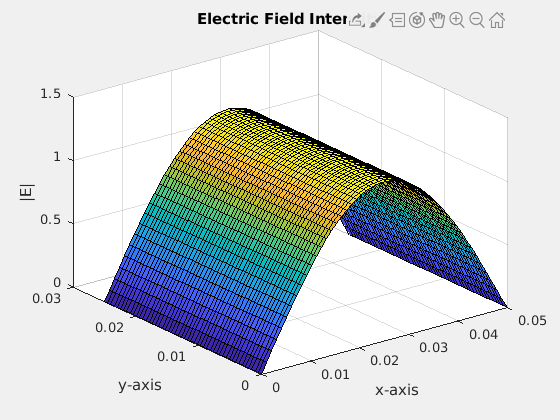

H0 = 1E-3;

x2 = linspace(0, a, numberOfPoints);
y2 = linspace(0, b, numberOfPoints);


[X, Y] = meshgrid(x2, y2);

phasorEx2 = j*omega*mu_0*ky*H0/h^2;
phasorEx2 = phasorEx2*cos(kx*X).*sin(ky*Y);

phasorEy2 = -j*omega*mu_0*kx*H0/h^2;
phasorEy2 = phasorEy2*sin(kx*X).*cos(ky*Y);

set(gcf, 'Visible', 'on')
surf(X, Y, abs(phasorEy2))
xlabel('x-axis')
ylabel('y-axis')
zlabel('|E|')
title('Electric Field Intensity')

%Getting colour map of E
numberOfPoints = 50

numberOfPoints = 50

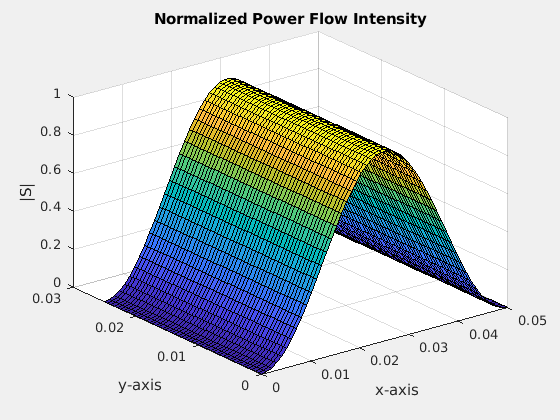

H0 = 1E-3;

x2 = linspace(0, a, numberOfPoints);
y2 = linspace(0, b, numberOfPoints);


[X, Y] = meshgrid(x2, y2);

S = sin(kx*X).^2;

set(gcf, 'Visible', 'on')
surf(X, Y, S)
xlabel('x-axis')
ylabel('y-axis')
zlabel('|S|')
title('Normalized Power Flow Intensity')